clc, clear all
syms psi q1 q2 q3 q4 q5 l1 l2 l3 l4 l5 a b c ul um un xu yu zu

## Simulacion

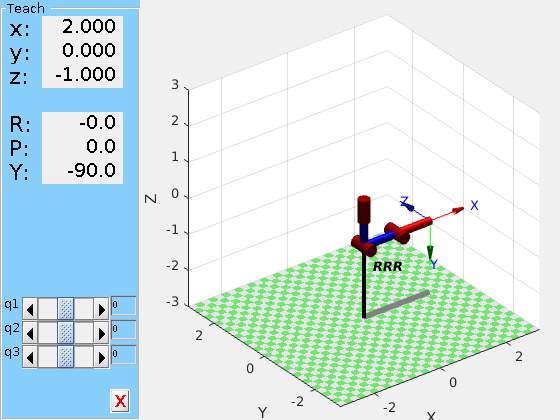

%L1 = -1; L2 = 1; L3 = 1; L4 = 1; L5 = 1;
L1 = 1; 
L2 = 1; 
L3 = 1;
L4 = 0.072;
L5 = 0.045;
% Primer Brazo
Lx(1) = Link([0 -L1 0 -pi/2]); 
Lx(2) = Link([0 0 L2 0 ]);
Lx(3) = Link([0 0 L3 0 ]);

robot = SerialLink(Lx);
robot.name = 'RRR';
robot.teach;

## Denavit-Hartembet Modelo Cinematico


H01 = D_H(q1,-l1,0,-pi/2)

$$H01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right) & 0\\ 0 & -1 & 0 & -l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H12 = D_H(q2,0,l2,0)

$$H12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H23 = D_H(q3,0,l3,0)

$$H23 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & l_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & l_{3}\,\sin\left(q_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H03 = H01*H12*H23

$$H03 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & -\sin\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ -\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{3}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right) & 0 & -l_{1}-l_{2}\,\sin\left(q_{2}\right)-l_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)-l_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


hx_1 = simplify(H03(1,4))

$$hx\_1 = \cos\left(q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\right)$$

hy_1 = simplify(H03(2,4))

$$hy\_1 = \sin\left(q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\right)$$

hz_1 = simplify(H03(3,4))

$$hz\_1 = -l_{1}-l_{3}\,\sin\left(q_{2}+q_{3}\right)-l_{2}\,\sin\left(q_{2}\right)$$


% hx = a*cos(psi)- b*sin(psi) + hx_1;
% hy = a*sin(psi)+ b*cos(psi) + hy_1;
% hz = c + hz_1;

J=jacobian([hx_1,hy_1,hz_1],[q1,q2,q3]);

J_p = simplify(derivative_matrix(J,q_p,q))

Undefined function or variable 'q_p'.


J1 = jacobian(J,q_p(1))

## +UAV